    % 参数
figure
hold on
 lambda = getLambda(0.4)     

lambda =     1.0000    1.0000    1.0000    0.9999    0.9996    0.9990    0.9980    0.9964    0.9940    0.9905    0.9859    0.9799    0.9723    0.9628    0.9514    0.9377    0.9217    0.9031    0.8819    0.8580    0.8313    0.8017    0.7694    0.7344    0.6967    0.6567    0.6144    0.5703    0.5246    0.4778    0.4305    0.3831    0.3364    0.2912    0.2483    0.2087    0.1733    0.1434    0.1203    0.1053    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


 plot(0:0.01:1, lambda)

  lambda = getLambda(2)     

lambda =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9990    0.9988    0.9987    0.9985    0.9982    0.9980    0.9977    0.9974    0.9971    0.9968    0.9964    0.9960    0.9955    0.9950    0.9945    0.9940    0.9934    0.9927    0.9920    0.9913    0.9905    0.9897    0.9889    0.9879    0.9870


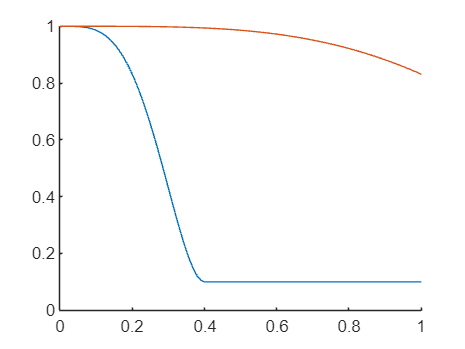

 plot(0:0.01:1, lambda)

function lambda = getLambda(cr)



    alpha1 = 0.1;
    alpha2 = 0.9;

% --- Step 2: 计算 θ ---
    theta = 0:0.01:1;

    % --- Step 3: 计算 m ---
    m = 1 - min(1, theta / cr);

    % --- Step 4: 计算 g(m) ---
    g_m = (1 - m).^4 .* (1 + 4*m);

    % --- Step 5: 计算 λ ---
    lambda = alpha1 + alpha2*(1 - g_m);
end
